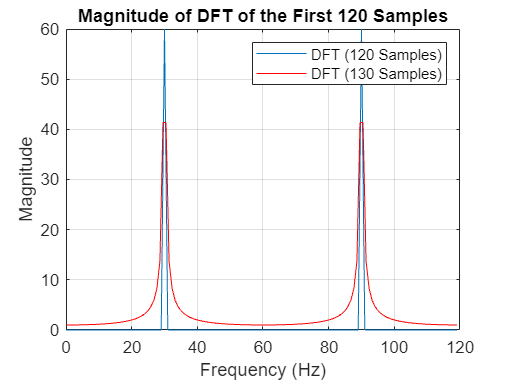

%q1
a = 1+mod(256,3); 
frequency = 15 * a; 
duration = 2; 
Fs = 120; 
T=1/Fs;
t=0:T:duration-T;
%q1(a)
y = sin(2 * pi * frequency * t);
samples = y(1:120);
N = length(samples);

frequencies = (0:N-1) * (Fs / N);
dft_120 = abs(fft(samples, N));
figure;
plot(frequencies, dft_120);
title('Magnitude of DFT of the First 120 Samples');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;
%q1(b)
samples_130 = y(1:130);

N_130 = length(samples_130);
frequencies_130 = (0:N_130-1) * (Fs / N_130);
dft_130 = abs(fft(samples_130, N_130));

hold on;
plot(frequencies_130, dft_130, 'r');
legend('DFT (120 Samples)', 'DFT (130 Samples)');
hold off

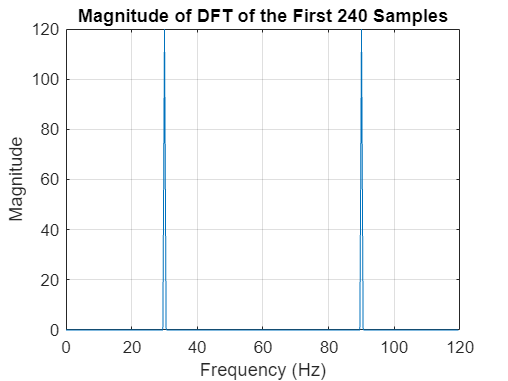



%q1(c)
%N=!120
samples_new = y(1:240);

N = length(samples_new);
frequencies = (0:N-1) * (Fs / N);
dft_240 = abs(fft(samples_new, N));

figure;
plot(frequencies, dft_240);
title('Magnitude of DFT of the First 240 Samples');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

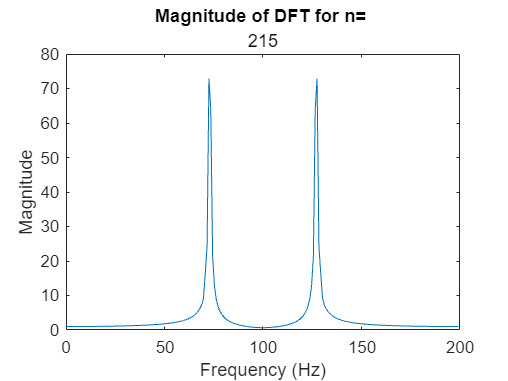

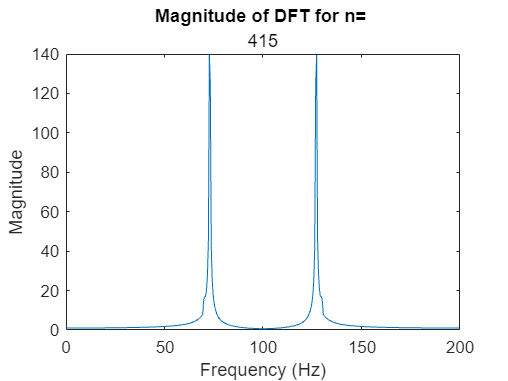

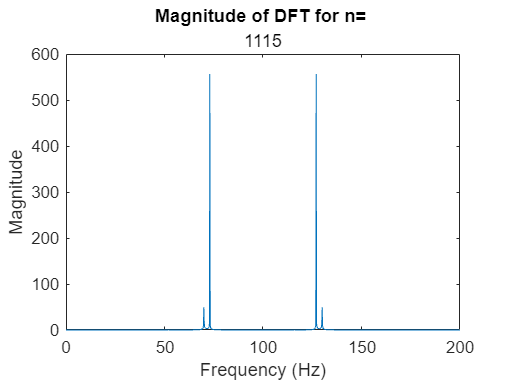

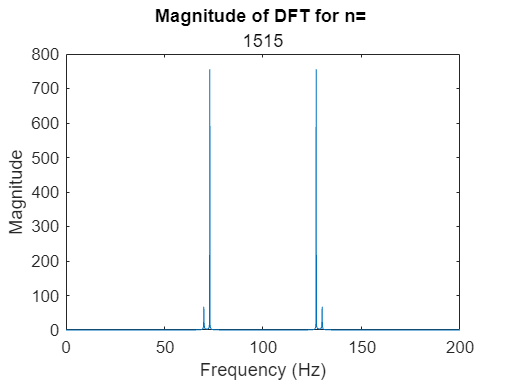

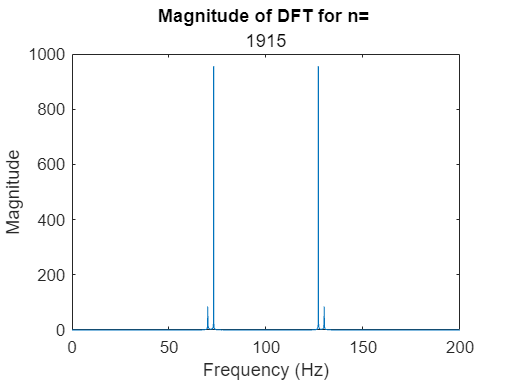

%Q2
A=140;
B=146;
duration = 10; 
Fs = 200; 
T=1/Fs;
t=0:T:duration-T;

y = 0.1*sin(A*pi*t) + cos(B*pi*t);



samples_len=[215;415;1115;1515;1915];

for i=1:5
    sample=y(1:samples_len(i));
    N=length(sample);
    frequencies= (0:N-1) * (Fs / N);
    dft= abs(fft(sample, N));
    figure;
    plot(frequencies, dft);
    title('Magnitude of DFT for n= ',num2str(samples_len(i)));
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');

   
end 

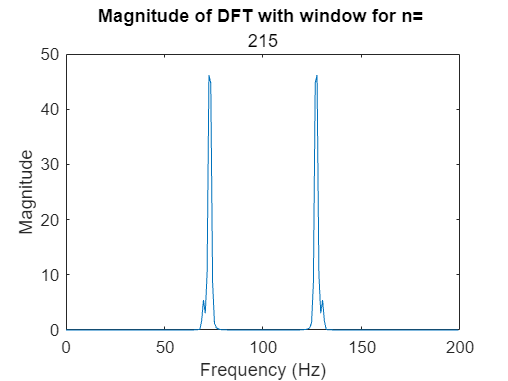

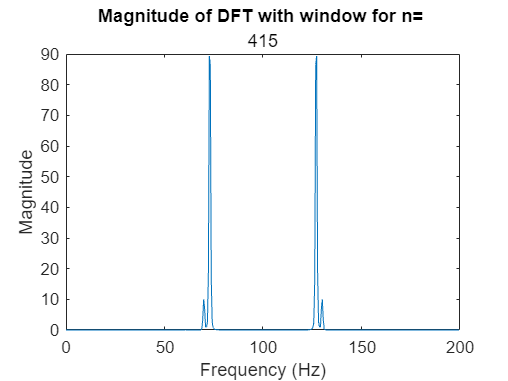

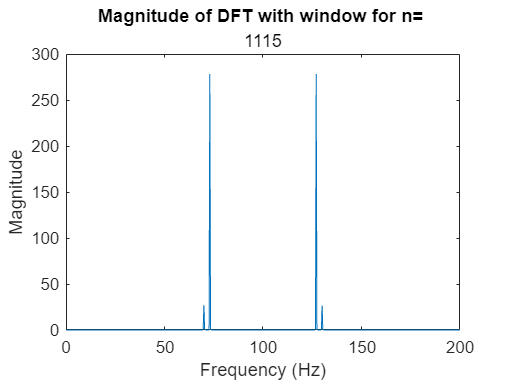

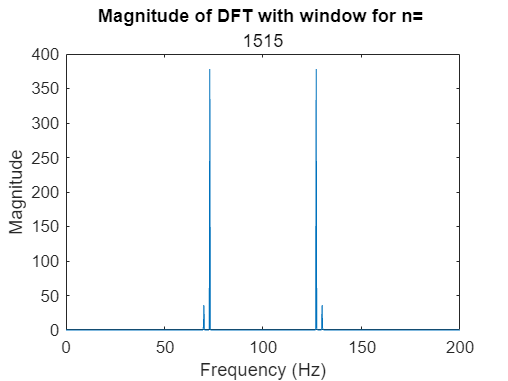

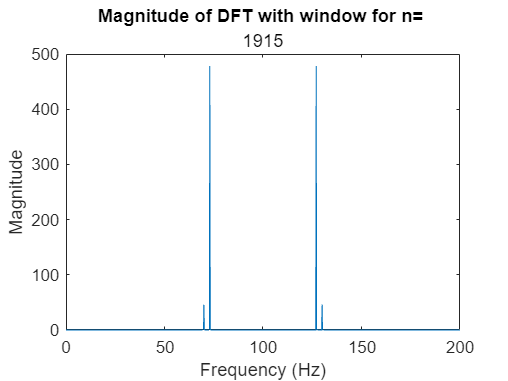

%q3
A=140;
B=146;
duration = 10; 
Fs = 200; 
T=1/Fs;
t=0:T:duration-T;

y = 0.1*sin(A*pi*t) + cos(B*pi*t);


samples_len=[215;415;1115;1515;1915];

for i=1:5
    sample=y(1:samples_len(i));
    N=length(sample);
    window=hann(N);
    sig_window=sample.*(window)';
    frequencies= (0:N-1) * (Fs / N);
    dft= abs(fft(sig_window, N));
    figure;
    plot(frequencies, dft);
    title('Magnitude of DFT with window for n= ',num2str(N));
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');

   
end   

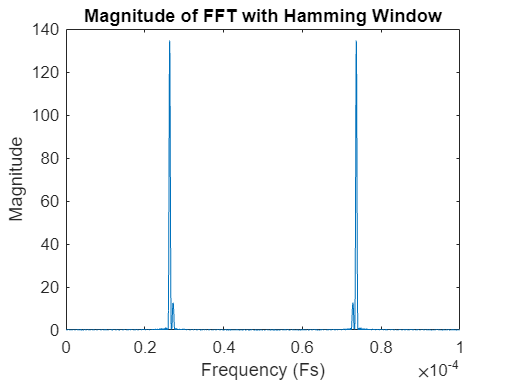

%q4
data = load('Exp4Data2.txt');
Fs = 1; 
T=1/Fs;
t=0:T:duration-T;
N = length(data);

%q4(a)
window = hamming(N);
data_window = data .* window';

n= 10000;
fft_new = fft(data_window, n);
freq = (0:n-1) * (Fs / n);
freq_normalized = freq / n;
figure;
plot(freq_normalized, abs(fft_new));
title('Magnitude of FFT with Hamming Window');
xlabel('Frequency (Fs)');
ylabel('Magnitude');


[~, max_indices] = maxk(abs(fft_new), 2);
frequencies = freq_normalized(max_indices);
disp(['Estimated Frequencies using Hamming Window: ', num2str(sort(frequencies))]);

Estimated Frequencies using Hamming Window: 2.632e-05   7.368e-05


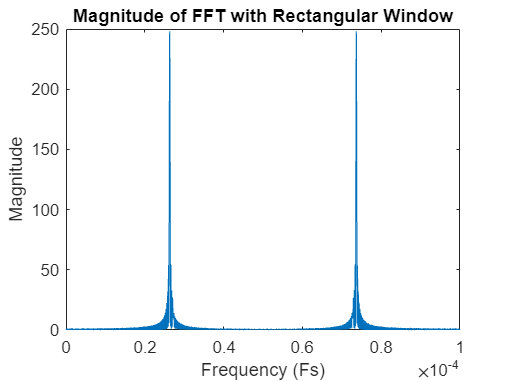


%q4(5)
window_rect = rectwin(N);
data_window_rect = data .* window_rect';
fft_rect = fft(data_window_rect, n);
figure;
plot(freq_normalized, abs(fft_rect));
title('Magnitude of FFT with Rectangular Window');
xlabel('Frequency (Fs)');
ylabel('Magnitude');


[~, max_indices] = maxk(abs(fft_rect), 2);
frequencies1 = freq_normalized(max_indices);
disp(['Estimated Frequencies using Rectangular Window: ', num2str(sort(frequencies1))]);

Estimated Frequencies using Rectangular Window: 2.632e-05   7.368e-05
